# Εργαστήριο Ψηφιακής Επεξεργασίας Σημάτων

## Συμπλήρωμα Αναφοράς 3ης Εργαστηριακής Άσκησης.

#### Λουδάρος Ιωάννης - 1067400

Εδώ περιλαμβάνεται ο κώδικας που χρησιμοποιήθηκε για την εκπόνηση της Άσκησης.

clear;clc;close all

## Άσκηση 1

### Απόκριση Συχνότητας του Συστήματος

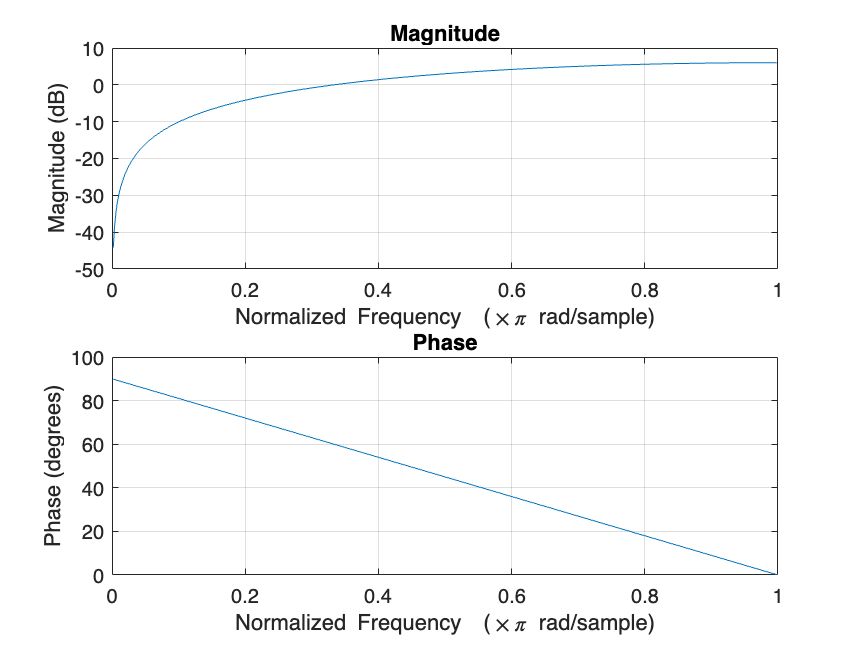

freqz([1 -1],1);

### Διαφόριση Σήματος Συνημιτόνου

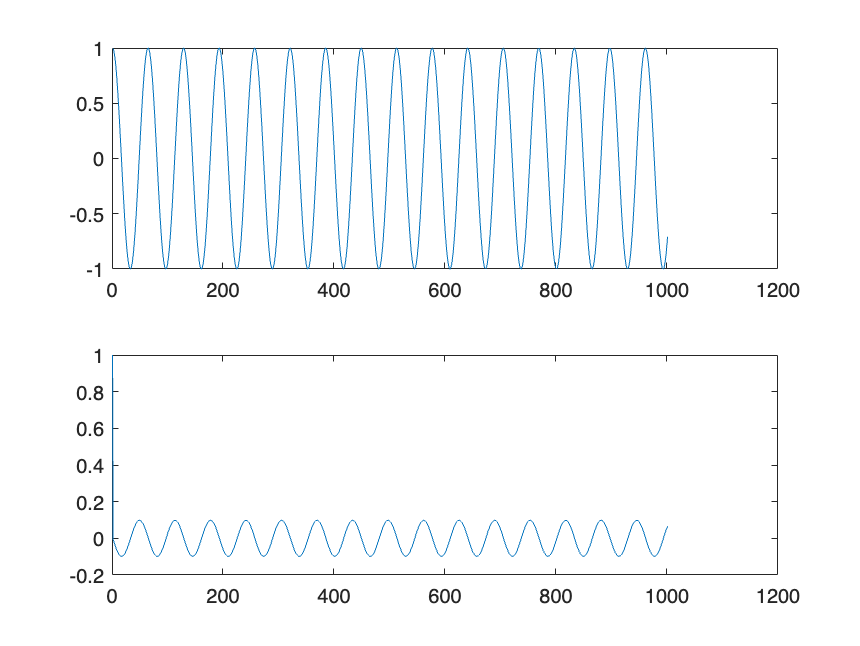

n = 0:1000;
x = cos(pi/32*n);
y = filter([1 -1],1,x);


figure
subplot(211);plot(x);
subplot(212);plot(y);

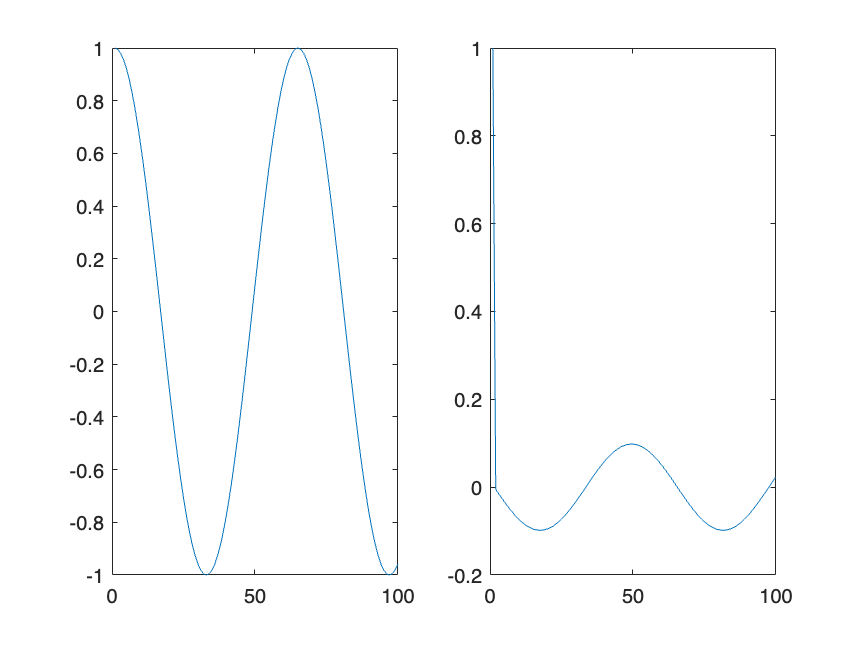


figure
subplot(121);plot(x(1:100));
subplot(122);plot(y(1:100));

### Φιλτράρισμα εικόνας

img = imread('photo.jpg');
img_deg = imread('photo-deg.jpg');

#### Κάθετη Διαφόριση  $\frac{\partial I\left(x,y\right)}{\partial y}$

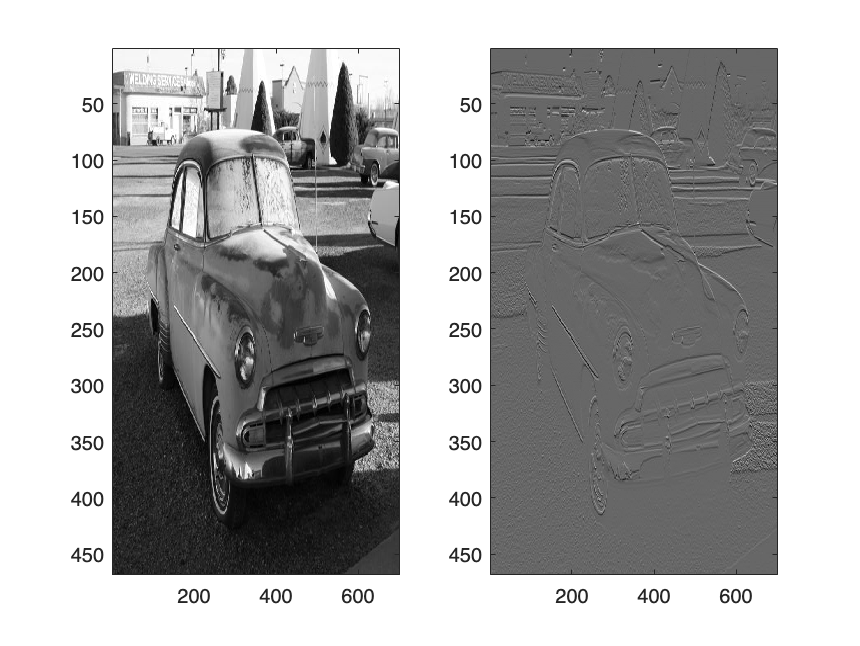

dy = filter([1 -1],1,img);

figure
subplot(121); imagesc(img); colormap gray; % εναλλακτικά imshow(uint8(img));
subplot(122);  imagesc(dy); colormap gray;

#### Οριζόντια Διαφόριση  $\frac{\partial I\left(x,y\right)}{\partial x}$

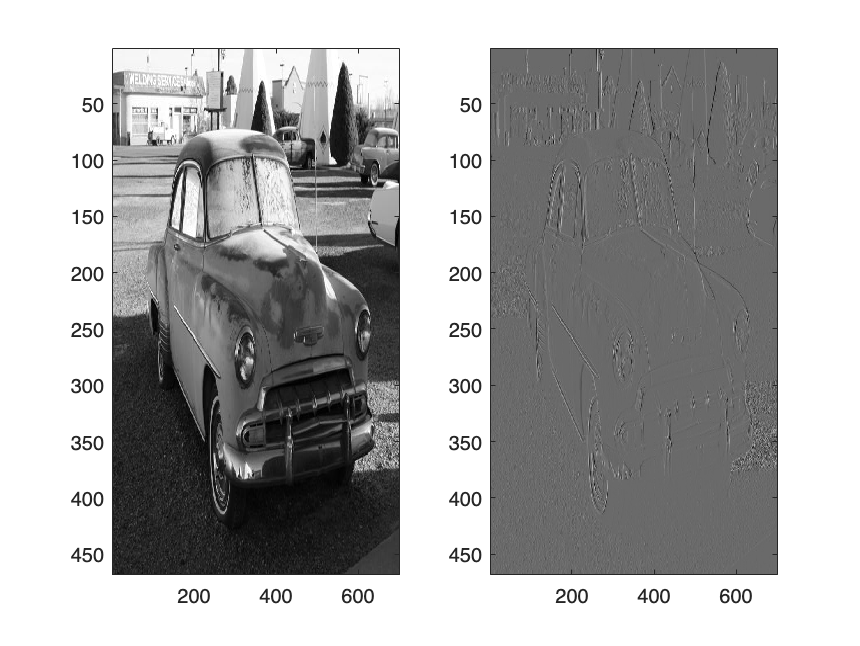

dx = filter([1 -1],1,img')';

figure
subplot(121); imagesc(img); colormap gray;
subplot(122);  imagesc(dx); colormap gray;

#### 
$$\frac{\partial^2 I\left(x,y\right)}{\partial x^2 }$$


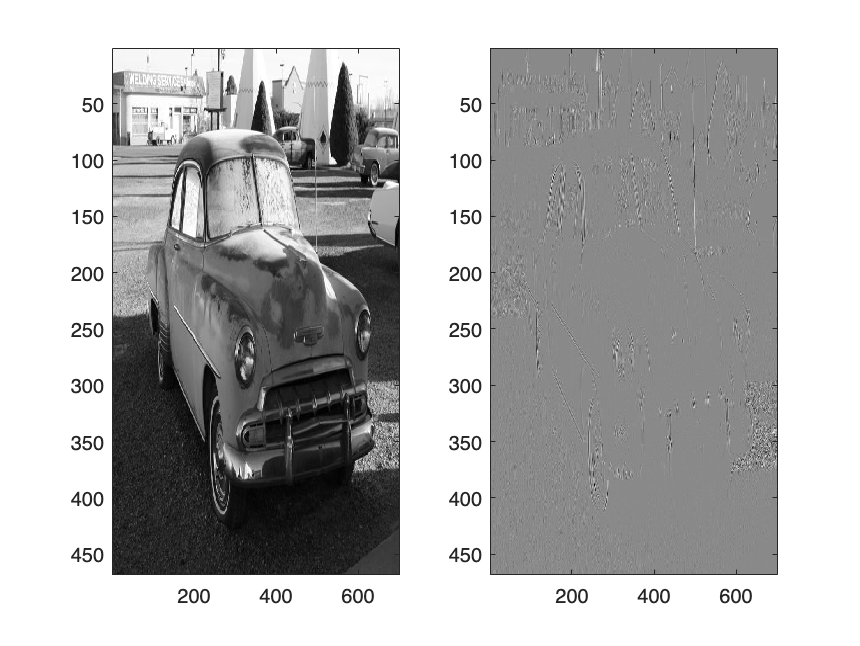

dxdx = filter([1 -1],1,dx')';

figure
subplot(121);   imagesc(img); colormap gray;
subplot(122);  imagesc(dxdx); colormap gray;

#### 
$$\frac{\partial^2 I\left(x,y\right)}{\partial y^2 }$$


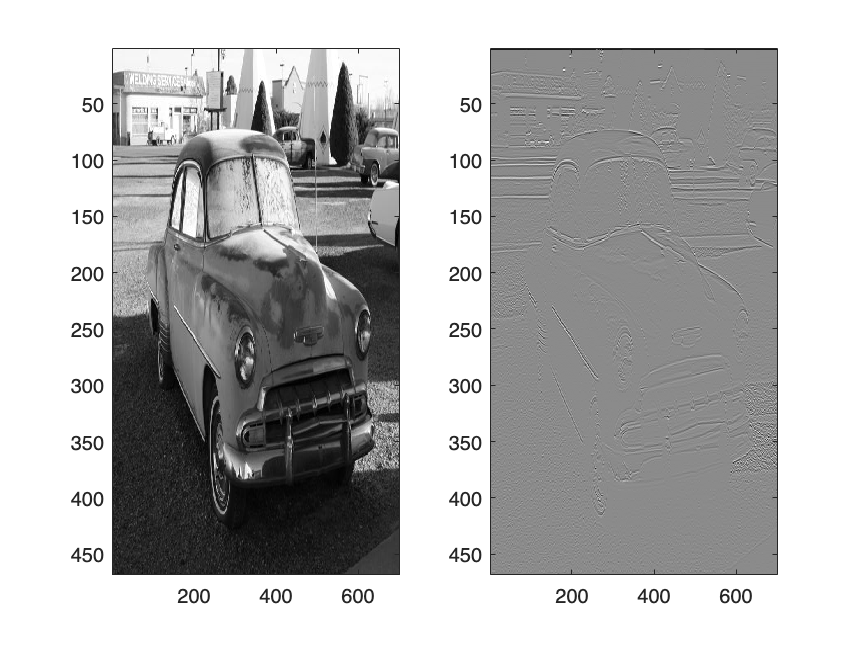

dydy = filter([1 -1],1,dy);

figure
subplot(121);  imagesc(img); colormap gray;
subplot(122); imagesc(dydy); colormap gray;

#### 
$$\frac{\partial^2 I\left(x,y\right)}{\partial x\partial y}$$


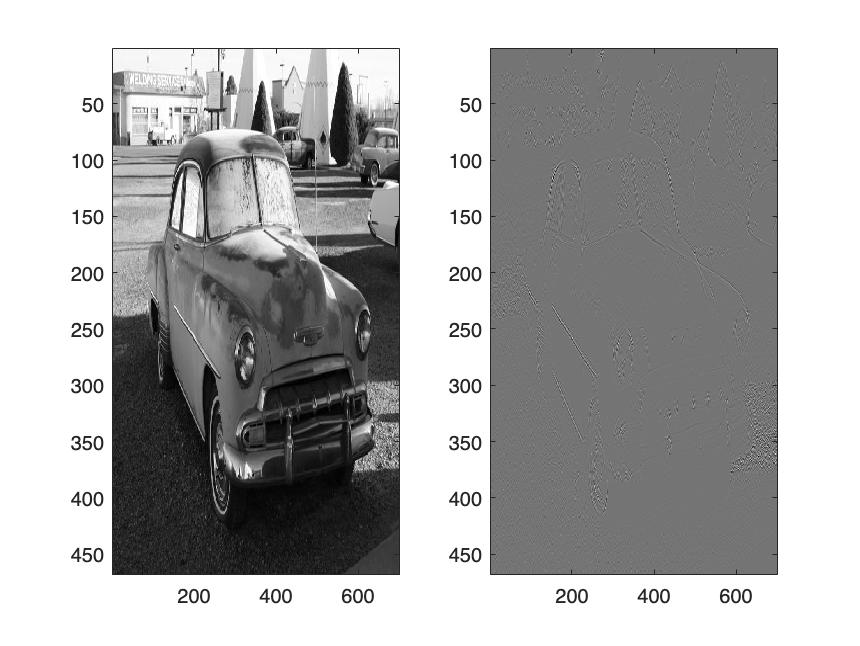

dxdy = filter([1 -1],1,dx);

figure
subplot(121);  imagesc(img); colormap gray;
subplot(122); imagesc(dxdy); colormap gray;

#### 
$$\frac{\partial^2 I\left(x,y\right)}{\partial y\partial x}$$


dydx = filter([1 -1],1,dy')';

figure
subplot(121);  imagesc(img); colormap gray;
subplot(122); imagesc(dydx); colormap gray;

### Χρήση δισδιάστατου Γραμμικού Χρονικά Αμετάβλητου Συστήματος

#### Χρήση της `filter2(*)`

N=6;

Κανονική εικόνα

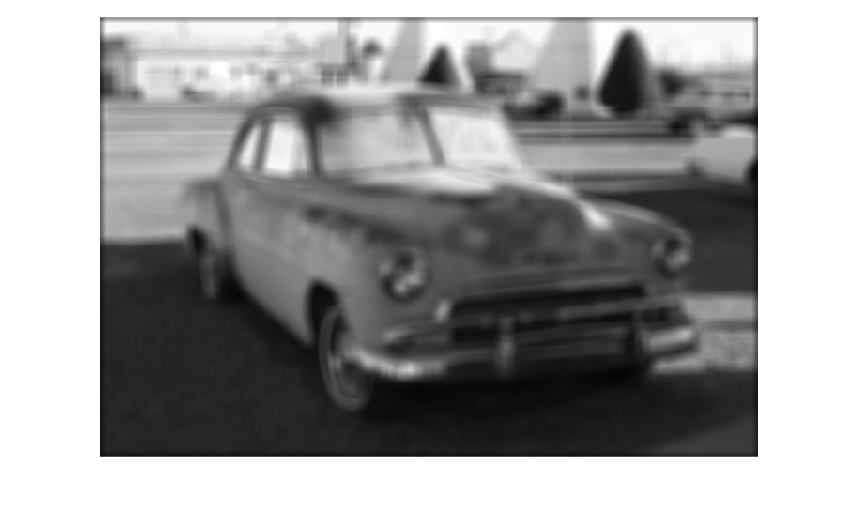

h = ones(2*N+1, 2*N+1) / (2*N+1)^2;
y = filter2(h,img);

figure
imshow(y/max(y(:)));

Εικόνα με θόρυβο

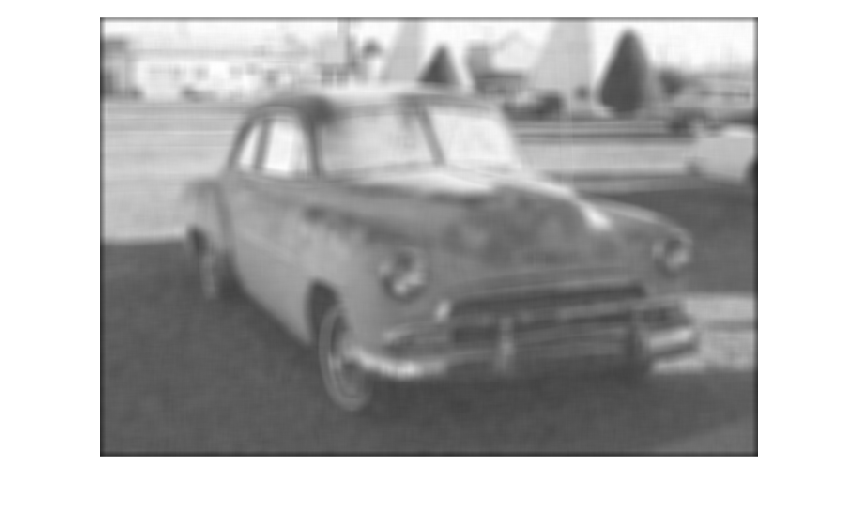

h = ones(2*N+1, 2*N+1) / (2*N+1)^2;
y = filter2(h,img_deg);

figure
imshow(y/max(y(:)));

#### Χρήση της medfilt2`(*)`

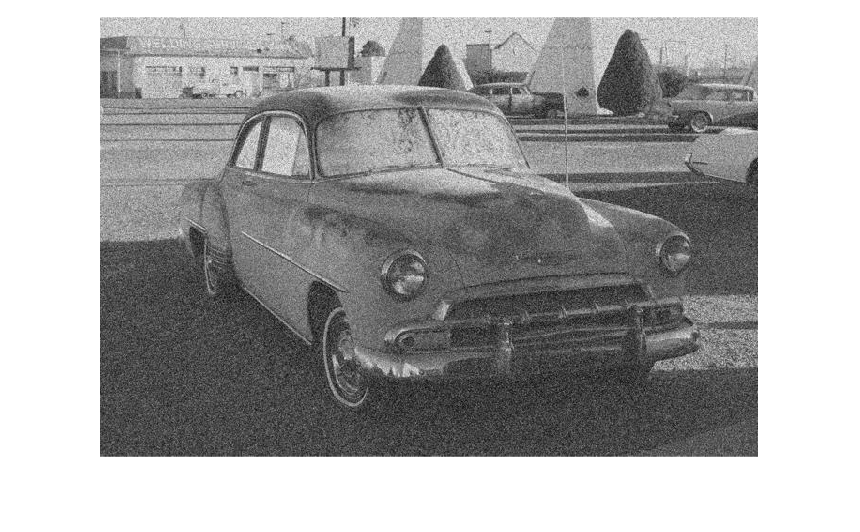

imshow(img_deg);

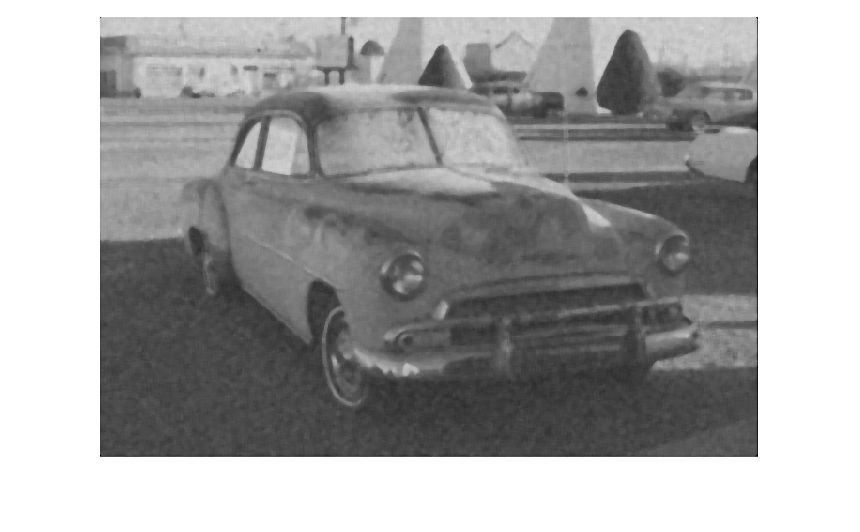

y = medfilt2(img_deg,[N N]);

figure
imshow(y);

## Άσκηση 2

### Φόρτωση Βίντεο και Επιλογή Πίξελ 

v = VideoReader('500fps.m4v');

i = 0;

while hasFrame(v)
    i = i+1;
    I = rgb2gray(im2double(readFrame(v)));
    x(i) = I(293,323);
end

#### Εύρεση συχνότητας μέσω Fourier

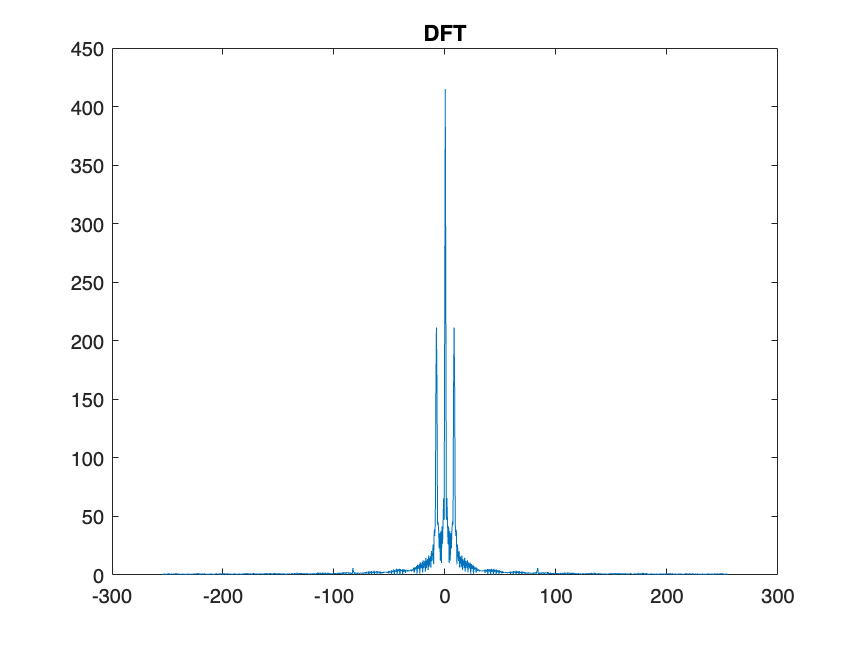

NumFFT = 1024;
F = linspace(-255, 255, NumFFT);


Fx = abs(fftshift(fft(x, NumFFT)));

figure
plot(F, Fx);
title("DFT");

### Φόρτωση Θορυβώδους Βίντεο και Επιλογή Πίξελ 

v_noisy = VideoReader('500fps_noisy.m4v');
N = 5;
i = 0;

yn = [];
yd = [];
while hasFrame(v_noisy)
    i = i+1;
    I = rgb2gray(im2double(readFrame(v_noisy)));
    H = medfilt2(I, [N N]);
    yn(i) = I(293,323);
    yd(i) = H(293,323);
end

#### Εύρεση συχνότητας μέσω Fourier για το θορυβώδες βίντεο.

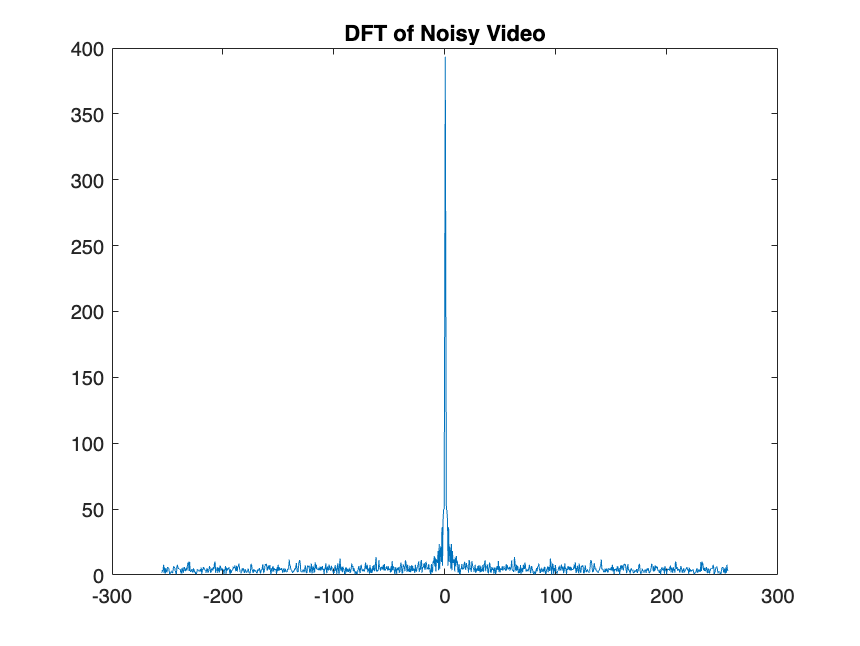

NumFFT = 1024;
F = linspace(-255, 255, NumFFT);

Fx_noisy = abs(fftshift(fft(yn, NumFFT)));
Fx_denoised = abs(fftshift(fft(yd, NumFFT)));



figure
plot(F, Fx_noisy);
title("DFT of Noisy Video");

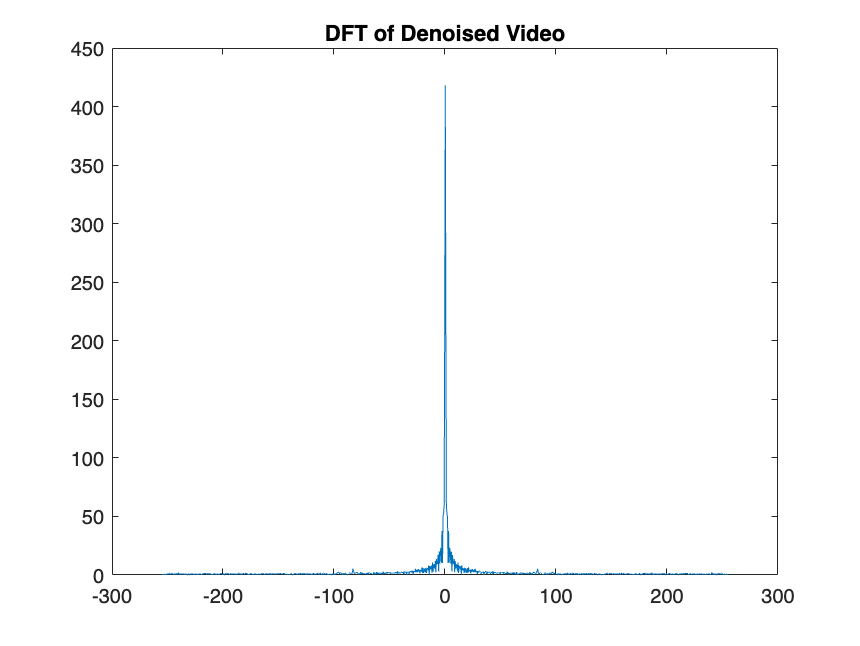




figure
plot(F, Fx_denoised);
title("DFT of Denoised Video");